# **Assignment**

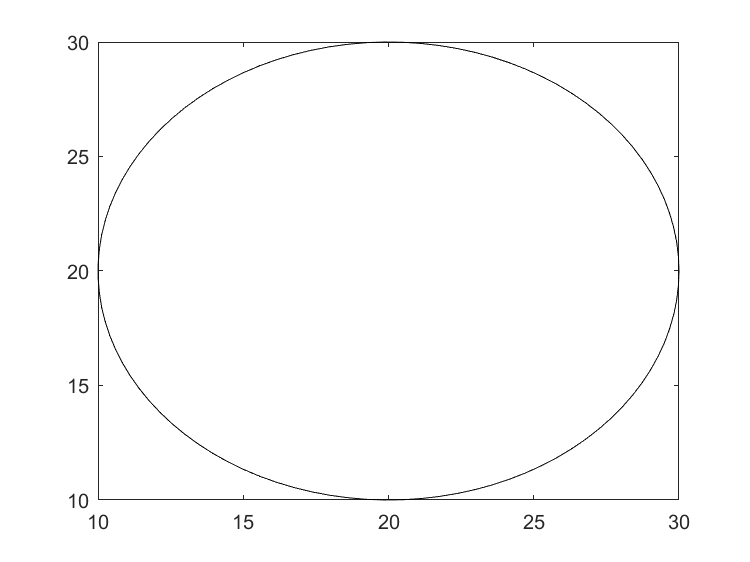

a=linspace(0,2*pi);
x=10*cos(a)+20;
y=10*sin(a)+20;
plot(x,y,"k");
hold on;

for t=linspace(0,2*pi)
    x1=10*cos(t)+20;
    y1=10*sin(t)+20;
    syms x2 y2;
    eq1=(x2-x1)^2+(y2-y1)^2==21^2;
    eq2=(x2)^2+y2^2==21^2;
    eq=[eq1 eq2];
    solutions=solve(eq,x2,y2);
    hold on
    x3=double(solutions.x2(2));
    y3=double(solutions.y2(2));
    x4=[0,x3,x1];
    y4=[0,y3,y1];
    p=plot(x4,y4,'r');
   
    pause(0.001);
    delete(p);
    
end
hold off